# **TU:  ODE-IVP (Part 2) - Higher order ODE**

**Numerical Programming: Y.-K. Kim**

Mod. 2024.10

# **II. 2nd order ODE-IVP**

## Problem

Solve for the response  y(t) and dy/dt of  an m-c-k system with a sinusoidal input Force u(t)

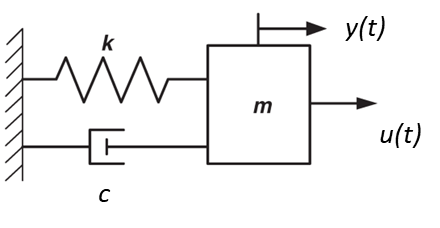

The function is defined in mckFun.m

Let, 

m=1; k=6.9; c=7; f=5;  

u(t)=Fin(t)=2*cos(2*pi*f*t)

## Part 1. MATLAB Tutorial

Lets define the mck ODE  functions as   odeFunc**_mck(t, vecY).**

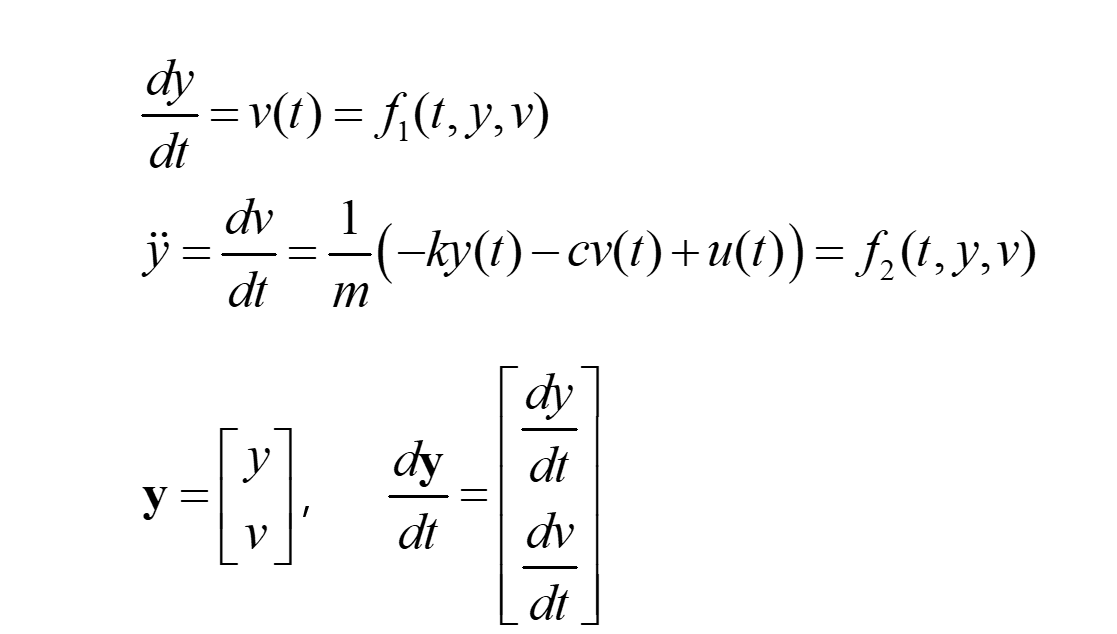

*See ****Function Definition*** ***Section**** at the end of this tutorial file*

### Initial Condition

% Initial Condition
% time
a=0;
b=1;
h=0.01;
N = (b-a)/h;


% IVP-Initial Condition
yINI = 0;
vINI = 0.2;



## MATLAB : ode45()

[tref, vecY] = ode45(@odeFunc_mck, a:h:b, [yINI, vINI]);

Plot the solution

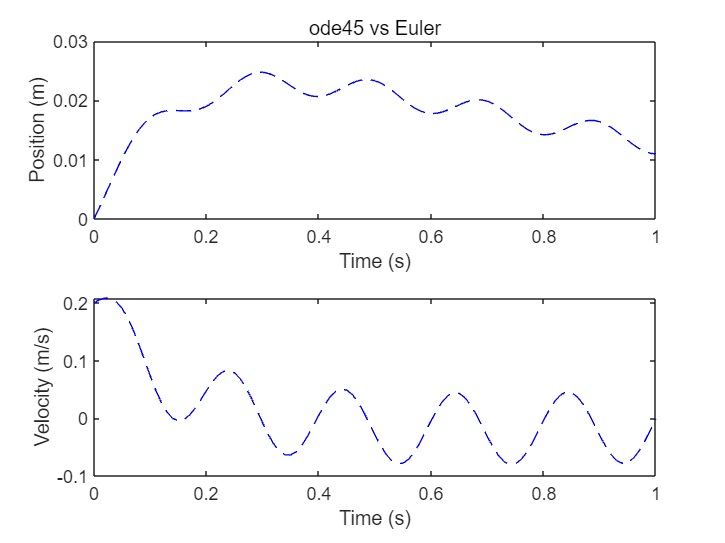

figure
subplot(2,1,1)
    plot(tref,vecY(:,1),'--b')
    xlabel('Time (s)')
    ylabel('Position (m)')
    title('ode45 vs Euler')
subplot(2,1,2)
    plot(tref,vecY(:,2),'--b')
    xlabel('Time (s)')
    ylabel('Velocity (m/s)')

## Exercise 

#### Exercise 1:  Euler's Explicit Method for 2nd-order ODE

**sys2EU_student.m**

First, fill-in this blank and complete the algorithm

% function [t, yE, vE] = sys2EU_student(gradF,a,b,h,yINI, vINI)

    % Variable Initialization
    N = (b-a)/h;    
    t=zeros(1,N+1);    
    yE=zeros(1,N+1);
    vE=zeros(1,N+1);

    % Initial Condition
    yE(1) = yINI;
    vE(1) = vINI;
    t(1)=a;


    % Euler Explicit ODE Method
    for i = 1:N
        t(i+1) = t(i) + h;        
        dYdt=odeFunc_mck(t(i),[yE(i),vE(i)]);

        yE(i+1) = yE(i) +(dYdt(1))*h; 
        vE(i+1) = vE(i)+(dYdt(2))*h;
    end

% end  % End of Function


Plot the solution and compare with MATLAB ode45

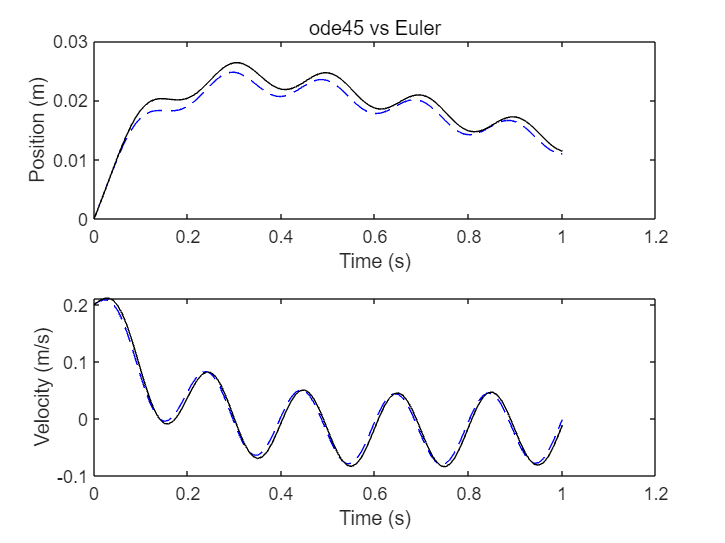

figure
subplot(2,1,1)
    plot(tref,vecY(:,1),'--b', t,yE,'k')
    xlabel('Time (s)')
    ylabel('Position (m)')
    title('ode45 vs Euler')
subplot(2,1,2)
    plot(tref,vecY(:,2),'--b', t,vE,'k')
    xlabel('Time (s)')
    ylabel('Velocity (m/s)')

### Exercise 2:  2nd order Runge-Kutta for 2nd-order ODE

**Create sys2RK2_student.m**

Modify the given template code

[t, yRK2, vRK2] = sys2RK2_student(@odeFunc_mck,a,b,h,yINI,vINI);

Plot the solution and compare with MATLAB ode45

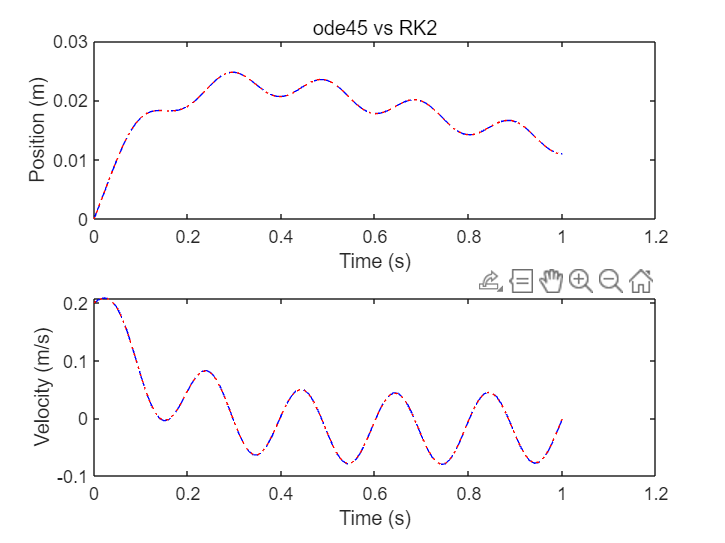

figure
subplot(2,1,1)
    plot(tref,vecY(:,1),'--b', t,yRK2,':r')
    xlabel('Time (s)')
    ylabel('Position (m)')
    title('ode45 vs RK2')
subplot(2,1,2)
    plot(tref,vecY(:,2),'--b', t,vRK2,':r')
    xlabel('Time (s)')
    ylabel('Velocity (m/s)')

### Exercise 3:  4nd order Runge-Kutta for 2nd-order ODE

**Create sys2RK4_student.m**

Modify the given template code

[t, yRK4, vRK4] = sys2RK4_student(@odeFunc_mck,a,b,h,yINI,vINI);

Plot the solution and compare with MATLAB ode45

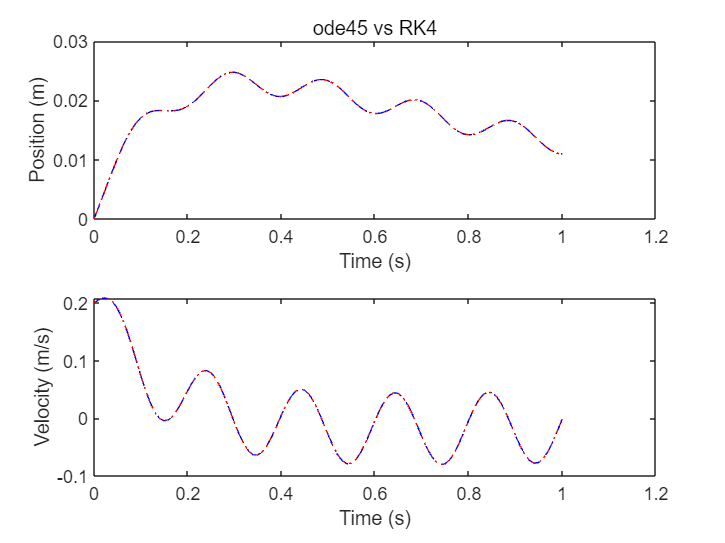

figure
subplot(2,1,1)
    plot(tref,vecY(:,1),'--b', t,yRK4,':r')
    xlabel('Time (s)')
    ylabel('Position (m)')
    title('ode45 vs RK4')
subplot(2,1,2)
    plot(tref,vecY(:,2),'--b', t,vRK4,':r')
    xlabel('Time (s)')
    ylabel('Velocity (m/s)')

# Function Definitions

**odeFunc_mck.m**

Lets define the mck ODE function   odeFunc**_RC(t,v)**

function [dYdt] = odeFunc_mck(t,vecY)
    % Input:
    %   vecY=[y ; v] 
    % Output:
    %   dYdt=[dydt ; dvdt] 

    % Variable Initialization
    dYdt=zeros(2,1);    
    
    % System Modeling parameters 
    m=1; k=6.9; c=10*0.7;
    FinDC=2;    f=5;
    Fin=FinDC*cos(2*pi*f*t);
    
    % Output    
    dYdt(1)=vecY(2); %=v
    dYdt(2)=1/m*(Fin-c*vecY(2)-k*vecY(1));

end 